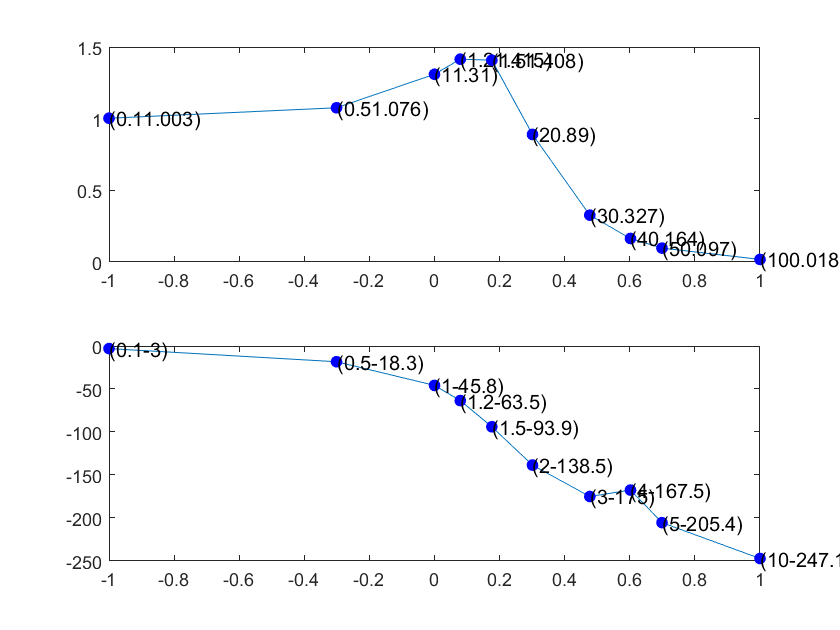

%绘制bode图
w=[0.1 0.5 1.0 1.2 1.5 2.0 3.0 4.0 5.0 10.0];
Gs=[1.003 1.076 1.310 1.415 1.408 0.890 0.327 0.164 0.097 0.018];
ang=[-3.0 -18.3 -45.8 -63.5 -93.9 -138.5 -175.0 -167.5 -205.4 -247.1];

subplot(2,1,1);
plot(log(w)./log(10),Gs);
%title(' ');
for i=1:10
line(log(w(i))./log(10),Gs(i),'marker','.','markeredgecolor','b','markersize',20);
y2str=['(',sprintf('%1.6g',w(i)),sprintf('%1.6g',Gs(i)),')'];
text(log(w(i))./log(10),Gs(i),{y2str});
end

subplot(2,1,2);
plot(log(w)./log(10),ang);

for i=1:10
line(log(w(i))./log(10),ang(i),'marker','.','markeredgecolor','b','markersize',20);
y2str=['(',sprintf('%1.6g',w(i)),sprintf('%1.6g',ang(i)),')'];
text(log(w(i))./log(10),ang(i),{y2str});
end

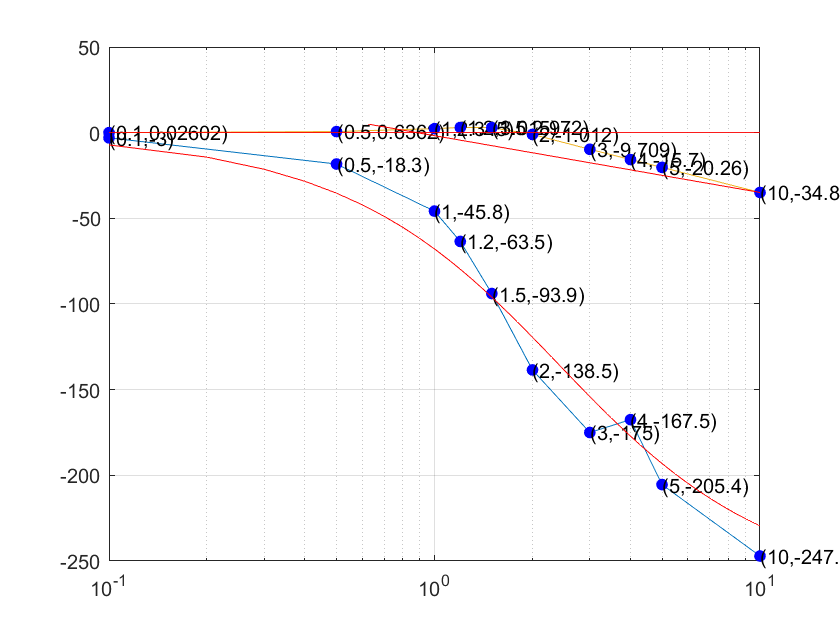

%修改版绘制bode图
w=[0.1 0.5 1.0 1.2 1.5 2.0 3.0 4.0 5.0 10.0];
Gs=[1.003 1.076 1.310 1.415 1.408 0.890 0.327 0.164 0.097 0.018];
ang=[-3.0 -18.3 -45.8 -63.5 -93.9 -138.5 -175.0 -167.5 -205.4 -247.1];
GGs=20*log(Gs)./log(10);   semilogx(w,GGs);
grid on;hold on;
for i=1:10
line(w(i),GGs(i),'marker','.','markeredgecolor','b','markersize',20);
y2str=['(',sprintf('%g',w(i)),',',sprintf('%1.4g',GGs(i)),')'];
text(w(i),GGs(i)+0.1,{y2str},1);
end
%画渐近线
y1=[0 0 0 0 0 0 0 0 0 0]; w2=[0 10.0];  y2=[5 GGs(10)];
w2(1)=10^(log(2)/log(10)-(5-GGs(2))/(GGs(6)-GGs(10))*(log(5)/log(10)))-0.1;
plot(w,y1,w2,y2,"Color",'r');

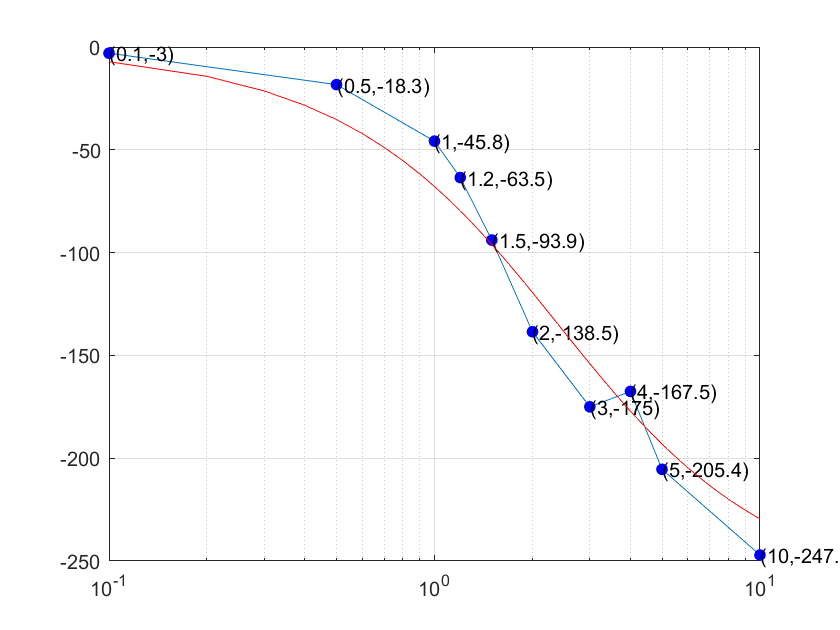

figure;  semilogx(w,ang);  grid on;  hold on;
for i=1:10
line(w(i),ang(i),'marker','.','markeredgecolor','b','markersize',20);
y2str=['(',sprintf('%1.6g',w(i)),',',sprintf('%1.6g',ang(i)),')'];
text(w(i),ang(i),{y2str});
end
%画渐近线
w1=0.1:0.1:10;  y1=-atan(w1/2.3512);  y1=y1/pi*180*3;  semilogx(w1,y1,'Color','r');

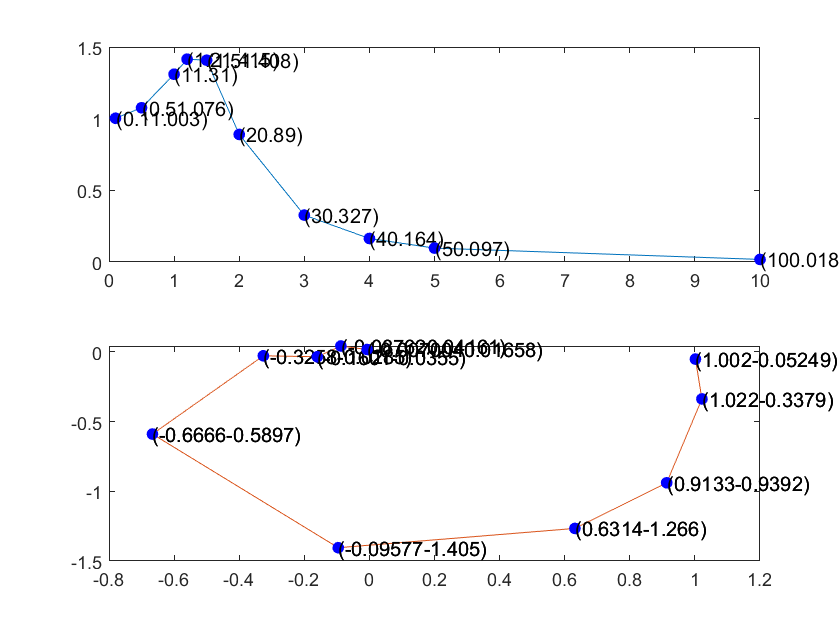

%绘制Nyquist图
w=[0.1 0.5 1.0 1.2 1.5 2.0 3.0 4.0 5.0 10.0];
Gs=[1.003 1.076 1.310 1.415 1.408 0.890 0.327 0.164 0.097 0.018];
ang=[-3.0 -18.3 -45.8 -63.5 -93.9 -138.5 -175.0 -167.5 -205.4 -247.1];
rad=ang/180*pi;
re=Gs.*cos(rad);
im=Gs.*sin(rad);
plot(re,im);
hold on;grid on;
for i=1:10
line(re(i),im(i),'marker','.','markeredgecolor','b','markersize',20);
y2str=['(',sprintf('%0.4g',re(i)),',',sprintf('%0.4g',im(i)),')'];
text(re(i)-0.1,im(i)-0.05,{y2str});
end